clear; clc; close all;

%% =========================
%% PARAMETERS
%% =========================
folder = 'C:\Users\benab\Downloads\OneDrive_1_4-17-2026';

B = 700;
B_rx = 700;
default_fs = 200000;
guard = 50;
augment_to_peak = 0.95;
play_pause = 4;
duration_sec = 3;

channel_names = {'Emna','erin','Harith','joe','elias','allen','ric','brenden','gianlorenzo'};
channel_freqs = [50000, 52000, 54000, 56000, 58000, 60000, 62000, 64000, 66000];

%% =========================
%% FIND ALL MAT FILES
%% =========================
files = dir(fullfile(folder, '*.mat'));

if isempty(files)
    error('No .mat files found in the folder.');
end

sc_files = {};
tc_files = {};

for k = 1:length(files)
    fname = files(k).name;

    if contains(fname, '_sc', 'IgnoreCase', true)
        sc_files{end+1} = fullfile(folder, fname);
    elseif contains(fname, '_tc', 'IgnoreCase', true)
        tc_files{end+1} = fullfile(folder, fname);
    end
end

fprintf('Found %d SC files and %d TC files.\n', length(sc_files), length(tc_files));

Found 9 SC files and 9 TC files.



%% =========================
%% LOAD, FORCE 3 SEC, BANDPASS, AUGMENT, COMBINE SC
%% =========================
sc_data = struct();
fs_sc = [];
targetLen_sc = [];

for k = 1:length(sc_files)
    [sig, fs, baseName] = loadSignalFromMat(sc_files{k}, default_fs);
    sig = sig(:);

    if isempty(fs_sc)
        fs_sc = fs;
        targetLen_sc = round(duration_sec * fs_sc);
    elseif fs ~= fs_sc
        error('Sampling frequency mismatch in SC files.');
    end

    sig = forceToExactLength(sig, targetLen_sc);
    fc = inferCarrierFromFilename(baseName, channel_names, channel_freqs);

    if fc == 52000
        sig_bp = bandlimitAroundCarrier(sig, fs, fc, 600, 30);
    elseif fc == 66000
        sig_bp = bandlimitAroundCarrier(sig, fs, fc, 600, 35);
    else
        sig_bp = bandlimitAroundCarrier(sig, fs, fc, B, guard);
    end

    sig_bp = augmentSignal(sig_bp, augment_to_peak);

    cleanName = matlab.lang.makeValidName(baseName);
    sc_data.(cleanName).signal = sig_bp;
    sc_data.(cleanName).fs = fs;
    sc_data.(cleanName).fc = fc;
end


combined_sc = zeros(targetLen_sc, 1);
sc_names = fieldnames(sc_data);

for k = 1:length(sc_names)
    combined_sc = combined_sc + sc_data.(sc_names{k}).signal;
end

fprintf('Combined SC signal created successfully.\n');

Combined SC signal created successfully.



%% =========================
%% LOAD, FORCE 3 SEC, BANDPASS, AUGMENT, COMBINE TC
%% =========================
tc_data = struct();
fs_tc = [];
targetLen_tc = [];

for k = 1:length(tc_files)
    [sig, fs, baseName] = loadSignalFromMat(tc_files{k}, default_fs);
    sig = sig(:);

    if isempty(fs_tc)
        fs_tc = fs;
        targetLen_tc = round(duration_sec * fs_tc);
    elseif fs ~= fs_tc
        error('Sampling frequency mismatch in TC files.');
    end

    sig = forceToExactLength(sig, targetLen_tc);
    fc = inferCarrierFromFilename(baseName, channel_names, channel_freqs);

    if fc == 52000
        sig_bp = bandlimitAroundCarrier(sig, fs, fc, 600, 30);
    elseif fc == 66000
        sig_bp = bandlimitAroundCarrier(sig, fs, fc, 600, 35);
    else
        sig_bp = bandlimitAroundCarrier(sig, fs, fc, B, guard);
    end

    sig_bp = augmentSignal(sig_bp, augment_to_peak);

    cleanName = matlab.lang.makeValidName(baseName);
    tc_data.(cleanName).signal = sig_bp;
    tc_data.(cleanName).fs = fs;
    tc_data.(cleanName).fc = fc;
end


combined_tc = zeros(targetLen_tc, 1);
tc_names = fieldnames(tc_data);

for k = 1:length(tc_names)
    combined_tc = combined_tc + tc_data.(tc_names{k}).signal;
end

fprintf('Combined TC signal created successfully.\n');

Combined TC signal created successfully.


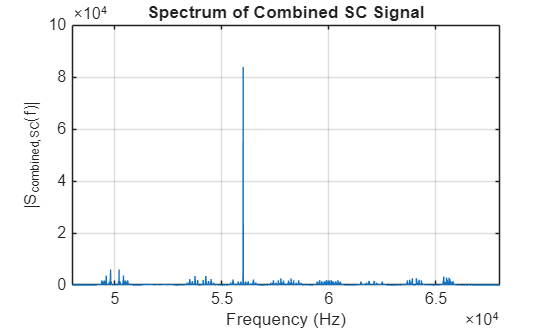


%% =========================
%% PLOT SPECTRA
%% =========================
Nsc = length(combined_sc);
fsc = linspace(-fs_sc/2, fs_sc/2, Nsc);
SCspec = fftshift(abs(fft(combined_sc)));

figure;
plot(fsc, SCspec);
title('Spectrum of Combined SC Signal');
xlabel('Frequency (Hz)');
ylabel('|S_{combined,SC}(f)|');
grid on;
xlim([48000 68000]);

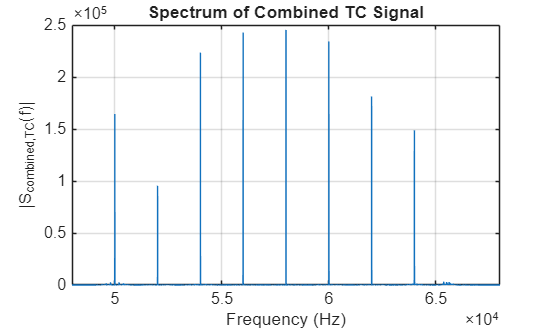


Ntc = length(combined_tc);
ftc = linspace(-fs_tc/2, fs_tc/2, Ntc);
TCspec = fftshift(abs(fft(combined_tc)));

figure;
plot(ftc, TCspec);
title('Spectrum of Combined TC Signal');
xlabel('Frequency (Hz)');
ylabel('|S_{combined,TC}(f)|');
grid on;
xlim([48000 68000]);


%% =========================
%% DEMODULATE ALL CHANNELS FROM COMBINED SC
%% =========================
disp('Demodulating channels from combined SC signal...');

Demodulating channels from combined SC signal...



recovered_sc = struct();
t_sc = (0:targetLen_sc-1)'/fs_sc;

for k = 1:length(channel_names)
    name = channel_names{k};
    fc = channel_freqs(k);
    fieldName = matlab.lang.makeValidName(name);

    isolated_rf = bandlimitAroundCarrier(combined_sc, fs_sc, fc, B, guard);

    if fc == 66000
        [b_sc_lp, a_sc_lp] = butter(8, 600/(fs_sc/2));
    else
        [b_sc_lp, a_sc_lp] = butter(8, B_rx/(fs_sc/2));
    end

    r = isolated_rf .* (2*cos(2*pi*fc*t_sc));
    x_rec = real(filtfilt(b_sc_lp, a_sc_lp, r));

    x_rec = forceToExactLength(x_rec, targetLen_sc);

    if fc == 52000
        x_rec = 1.4 * x_rec;
    end

    x_rec = 0.95 * x_rec / max(abs(x_rec) + eps);

    recovered_sc.(fieldName) = x_rec;

    outname = fullfile(folder, [name '_recovered_from_combined_sc.wav']);
    audiowrite(outname, x_rec, fs_sc);

    fprintf('Saved %s\n', outname);
end

Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\Emna_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\erin_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\Harith_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\joe_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\elias_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\allen_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\ric_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\brenden_recovered_from_combined_sc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\gianlorenzo_recovered_from_combined_sc.wav



%% =========================
%% DEMODULATE ALL CHANNELS FROM COMBINED TC
%% =========================
disp('Demodulating channels from combined TC signal...');

Demodulating channels from combined TC signal...



recovered_tc = struct();

for k = 1:length(channel_names)
    name = channel_names{k};
    fc = channel_freqs(k);
    fieldName = matlab.lang.makeValidName(name);

    if fc == 52000
        isolated_rf = bandlimitAroundCarrier(combined_tc, fs_tc, fc, 600, 30);
        [b_tc_lp, a_tc_lp] = butter(8, 700/(fs_tc/2));
    elseif fc == 66000
        isolated_rf = bandlimitAroundCarrier(combined_tc, fs_tc, fc, 600, 35);
        [b_tc_lp, a_tc_lp] = butter(8, 650/(fs_tc/2));
    else
        isolated_rf = bandlimitAroundCarrier(combined_tc, fs_tc, fc, B, guard);
        [b_tc_lp, a_tc_lp] = butter(8, B_rx/(fs_tc/2));
    end

    env_tc = abs(isolated_rf);
    env_tc = env_tc - mean(env_tc);

    x_rec = real(filtfilt(b_tc_lp, a_tc_lp, env_tc));
    x_rec = forceToExactLength(x_rec, targetLen_tc);

    if fc == 52000
        x_rec = 2.2 * x_rec;
    end

    x_rec = 0.95 * x_rec / max(abs(x_rec) + eps);

    recovered_tc.(fieldName) = x_rec;

    outname = fullfile(folder, [name '_recovered_from_combined_tc.wav']);
    audiowrite(outname, x_rec, fs_tc);

    fprintf('Saved %s\n', outname);
end

Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\Emna_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\erin_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\Harith_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\joe_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\elias_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\allen_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\ric_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\brenden_recovered_from_combined_tc.wav
Saved C:\Users\benab\Downloads\OneDrive_1_4-17-2026\gianlorenzo_recovered_from_combined_tc.wav



%% =========================
%% SAVE CLEANED COMBINED SIGNALS
%% =========================
save(fullfile(folder, 'combined_sc_cleaned.mat'), 'combined_sc', 'fs_sc');
save(fullfile(folder, 'combined_tc_cleaned.mat'), 'combined_tc', 'fs_tc');

%% =========================
%% PLAY ALL RECOVERED SIGNALS FROM SC
%% =========================
disp('Playing all recovered SC signals...');

Playing all recovered SC signals...



for k = 1:length(channel_names)
    name = channel_names{k};
    fieldName = matlab.lang.makeValidName(name);

    fprintf('\nPlaying %s from combined SC...\n', name);
    soundsc(recovered_sc.(fieldName), fs_sc);
    pause(play_pause);
end


Playing Emna from combined SC...

Playing erin from combined SC...

Playing Harith from combined SC...

Playing joe from combined SC...

Playing elias from combined SC...

Playing allen from combined SC...

Playing ric from combined SC...

Playing brenden from combined SC...

Playing gianlorenzo from combined SC...



%% =========================
%% PLAY ALL RECOVERED SIGNALS FROM TC
%% =========================
disp('Playing all recovered TC signals...');

Playing all recovered TC signals...



for k = 1:length(channel_names)
    name = channel_names{k};
    fieldName = matlab.lang.makeValidName(name);

    fprintf('\nPlaying %s from combined TC...\n', name);
    soundsc(recovered_tc.(fieldName), fs_tc);
    pause(play_pause);
end


Playing Emna from combined TC...

Playing erin from combined TC...

Playing Harith from combined TC...

Playing joe from combined TC...

Playing elias from combined TC...

Playing allen from combined TC...

Playing ric from combined TC...

Playing brenden from combined TC...

Playing gianlorenzo from combined TC...



%% =========================
%% LOCAL FUNCTIONS
%% =========================
function [sig, fs, baseName] = loadSignalFromMat(filepath, default_fs)
    data = load(filepath);
    vars = fieldnames(data);

    fs = [];
    sig = [];

    for i = 1:length(vars)
        val = data.(vars{i});

        if strcmpi(vars{i}, 'fs')
            fs = val;
        elseif isnumeric(val) && isvector(val) && length(val) > 1000
            sig = val;
        end
    end

    if isempty(sig)
        error('Could not find signal vector in file: %s', filepath);
    end

    if isempty(fs)
        fs = default_fs;
        fprintf('Warning: fs not found in %s -> assuming fs = %d Hz\n', filepath, default_fs);
    end

    [~, name, ~] = fileparts(filepath);
    baseName = name;
end

function sig_out = forceToExactLength(sig, targetLen)
    sig = sig(:);

    if length(sig) >= targetLen
        sig_out = sig(1:targetLen);
    else
        sig_out = [sig; zeros(targetLen - length(sig), 1)];
    end
end

function fc = inferCarrierFromFilename(baseName, channel_names, channel_freqs)
    fc = [];

    for ii = 1:length(channel_names)
        if contains(baseName, channel_names{ii}, 'IgnoreCase', true)
            fc = channel_freqs(ii);
            return;
        end
    end

    error('Could not infer carrier frequency from filename: %s', baseName);
end

function sig_bp = bandlimitAroundCarrier(sig, fs, fc, B, guard)
    low = fc - (B + guard);
    high = fc + (B + guard);

    if low <= 0
        error('Invalid bandpass lower edge for fc = %.1f Hz', fc);
    end

    Wn = [low high] / (fs/2);
    [b, a] = butter(8, Wn, 'bandpass');

    sig_bp = real(filtfilt(b, a, sig));
end

function y = augmentSignal(x, target_peak)
    x = real(x);
    peak = max(abs(x));

    if peak < eps
        y = x;
    else
        y = (target_peak / peak) * x;
    end
end